# Kullback Leibler Distance

clear; close all; clc;
main_dir = get_data_root();
path = fullfile(main_dir,'Figures/Ingvild/Ephys/Stability/Quantification');
save_path = fullfile(main_dir,'CompiledData');
path2 = fullfile(path, 'KLd');
path3 = fullfile(path2, 'OccupancyCorrected','NotPenalized');

Error using load
Unable to find file or directory "E:\Ingvild\Analysis\CompiledData/All_1D_spatial_maps.mat".

load(fullfile(save_path,'All_1D_spatial_maps.mat'));

animalID = [65622,63383,67330,67456,66922,65588,67324,67141];
animals = length(animalID);
gen = {'Control','Experimental'};
trials = 25;
session = 6;
day = 1:6;
spatial_bin = 100^2;
colors = {'#284B5E','#BC554C'};
control = [1,2,3,4];
experimental = [5,6,7,8];

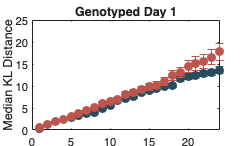

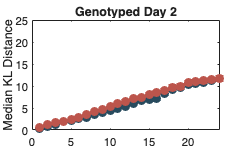

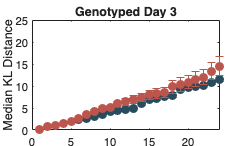

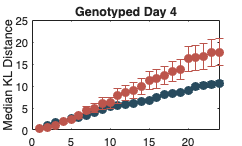

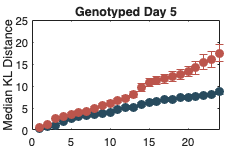

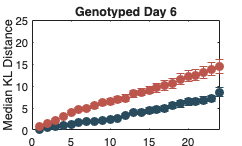

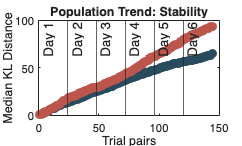


Linear mixed-effects model fit by ML

Model information:
    Number of observations            1201
    Fixed effects coefficients           2
    Random effects coefficients          8
    Covariance parameters                2

Formula:
    KL ~ 1 + Group + (1 | Animal)

Model fit statistics:
    AIC       BIC       LogLikelihood    Deviance
    8630.7    8651.1    -4311.4          8622.7  

Fixed effects coefficients (95% CIs):
    Name                   Estimate    SE         tStat     DF      pValue        Lower      Upper 
    {'(Intercept)'}        7.8183      0.35551    21.992    1199    2.5129e-90     7.1209    8.5158
    {'Group'      }        1.6733      0.50593    3.3073    1199    0.00096985    0.68067    2.6659

Random effects covariance parameters (95% CIs):
Group: Animal (8 Levels)
    Name1                  Name2                  Type           Estimate    Lower    Up

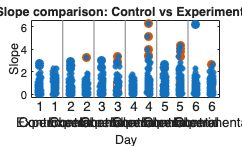

% set to 1 for corrected and 2 non-corrected;
occ_correct = 1;

set_path = {path3,path2};
for a = 1:animals
    for s = 1:session

        if occ_correct == 1

            maps = all_spatial_maps_1D_occ_corrected{s,a};
            cell_numb = length(maps);

            if isempty(maps)
                continue
            else

                % restrict to only overlapping bins in t and t+1
                distance = nan(cell_numb,24);
                for c = 1:cell_numb

                    spatial_activity = maps{1,c};

                    for t = 1:trials

                        if t == trials
                            continue
                        else
                            % find the overlapping bins
                            activity_t1 = spatial_activity(:,t);
                            activity_t2 = spatial_activity(:,t+1);
                            valid_idx = ~isnan(activity_t1) & ~isnan(activity_t2);

                            pij = activity_t1(valid_idx) + 1e-5;                        % avoid 0 probability
                            qij = activity_t2(valid_idx) + 1e-5;                        % avoid 0 probability                       

                            P = pij';          
                            Q = qij';

                            KLD = pij.*log(pij./qij) + (qij-pij);
                            kld_t =sum(KLD)/length(qij);
                            all_kld(t) = kld_t;
                        end
                    end

                    distance(c,:) = all_kld;

                end

                cumulative_distance = cumsum(distance,2);


                animal_name = mat2str(animalID(a));
                current_genotype = gen(animal_genotype(a));
                name = strcat('Day-',mat2str(day(s)),'-Animal-',animal_name,'-',current_genotype);

                figure("Visible","off")
                boxplot(cumulative_distance)
                yticks(0:5:35)
                ylim([0 35])
                xlabel('Trial Pairs')
                ylabel('KL Distance')
                title(name)


                fighandle = (strcat(sprintf('Day %d',s),';',sprintf('Animal %d',a)));
                save_figure(path3,fighandle);

                close;

                all_cumsum{s,a} = cumulative_distance;
                median_population{s,a} = median(cumulative_distance);
            end


        else
            maps = all_spatial_maps_1D{s,a};
            cell_numb = length(maps);

            if isempty(maps)
                continue
            else

                % restrict to only overlapping bins in t and t+1
                for c = 1:cell_numb

                    spatial_activity = maps{1,c};

                    for t = 1:trials

                        if t == trials
                            continue
                        else
                            % Avoid prob of 0, add small numb to all prob
                            spatial_activity_corrected = spatial_activity + 1e-5;
                            pij = spatial_activity_corrected(:,t);
                            qij = spatial_activity_corrected(:,t+1);

                            zero_flag = (qij == 0) & (pij ~= 0);


                            P = pij';          
                            Q = qij';

                            KLD = pij.*log(pij./qij) + (qij-pij);
                            kld_t =sum(KLD)/spatial_bin;
                            all_kld(t) = kld_t;
                        end
                    end

                    distance(c,:) = all_kld;

                end

                cumulative_distance = cumsum(distance,2);


                animal_name = mat2str(animalID(a));
                current_genotype = gen(animal_genotype(a));
                name = strcat('Day-',mat2str(day(s)),'-Animal-',animal_name,'-',current_genotype);

                figure("Visible","off")
                boxplot(cumulative_distance)
                yticks(0:5:20)
                ylim([0 20])
                xlabel('Trial Pairs')
                ylabel('KL distance')
                title(name)


                fighandle = (strcat(sprintf('Day %d',s),';',sprintf('Animal %d',a)));
                save_figure(path2,fighandle);

                close;

                all_cumsum{s,a} = cumulative_distance;
                median_population{s,a} = median(cumulative_distance);
            end
        end
    end
end

save(fullfile(save_path,'KLdistance.mat'),"cumsum_days","all_cumsum","animal_genotype");